# Pick and Place Using RRT for Manipulators

Using manipulators to pick and place objects in an environment may require path planning algorithms like the rapidly-exploring random tree planner. The planner explores in the joint-configuration space and searches for a collision-free path between different robot configurations. This example shows how to use the [`manipulatorRRT`](docid:robotics_ref#mw_ebddba4d-1dbe-4a60-b626-74349473c4bb) object to tune the planner parameters and plan a path between two joint configurations based on a [`rigidBodyTree`](docid:robotics_ref#bvan8uq-1) robot model of the Franka Emika™ Panda robot. After tuning the planner parameters, the robot manipulator plans a path to move a can from one place to another.

## Load Robot Model and Environment

Load the robot and its environment using the `exampleHelperLoadPickAndPlaceRRT` function. The function outputs three variables:

- `franka` *—* A Franka Emika Panda robot model as a `rigidBodyTree` object. The model has been modified to remove some adjacent collision meshes that are always in collision and adjust position limits based on feasibility.

- `config` *—* An initial configuration of joint positions for the robot.

- `env` *— *A set collision objects as a cell array that represent the robot's environment. The path planner checks for self-collisions and collisions with this environment.

[franka,config,env] = exampleHelperLoadPickAndPlaceRRT;

Visualize the robot model's collision meshes and the environment objects.

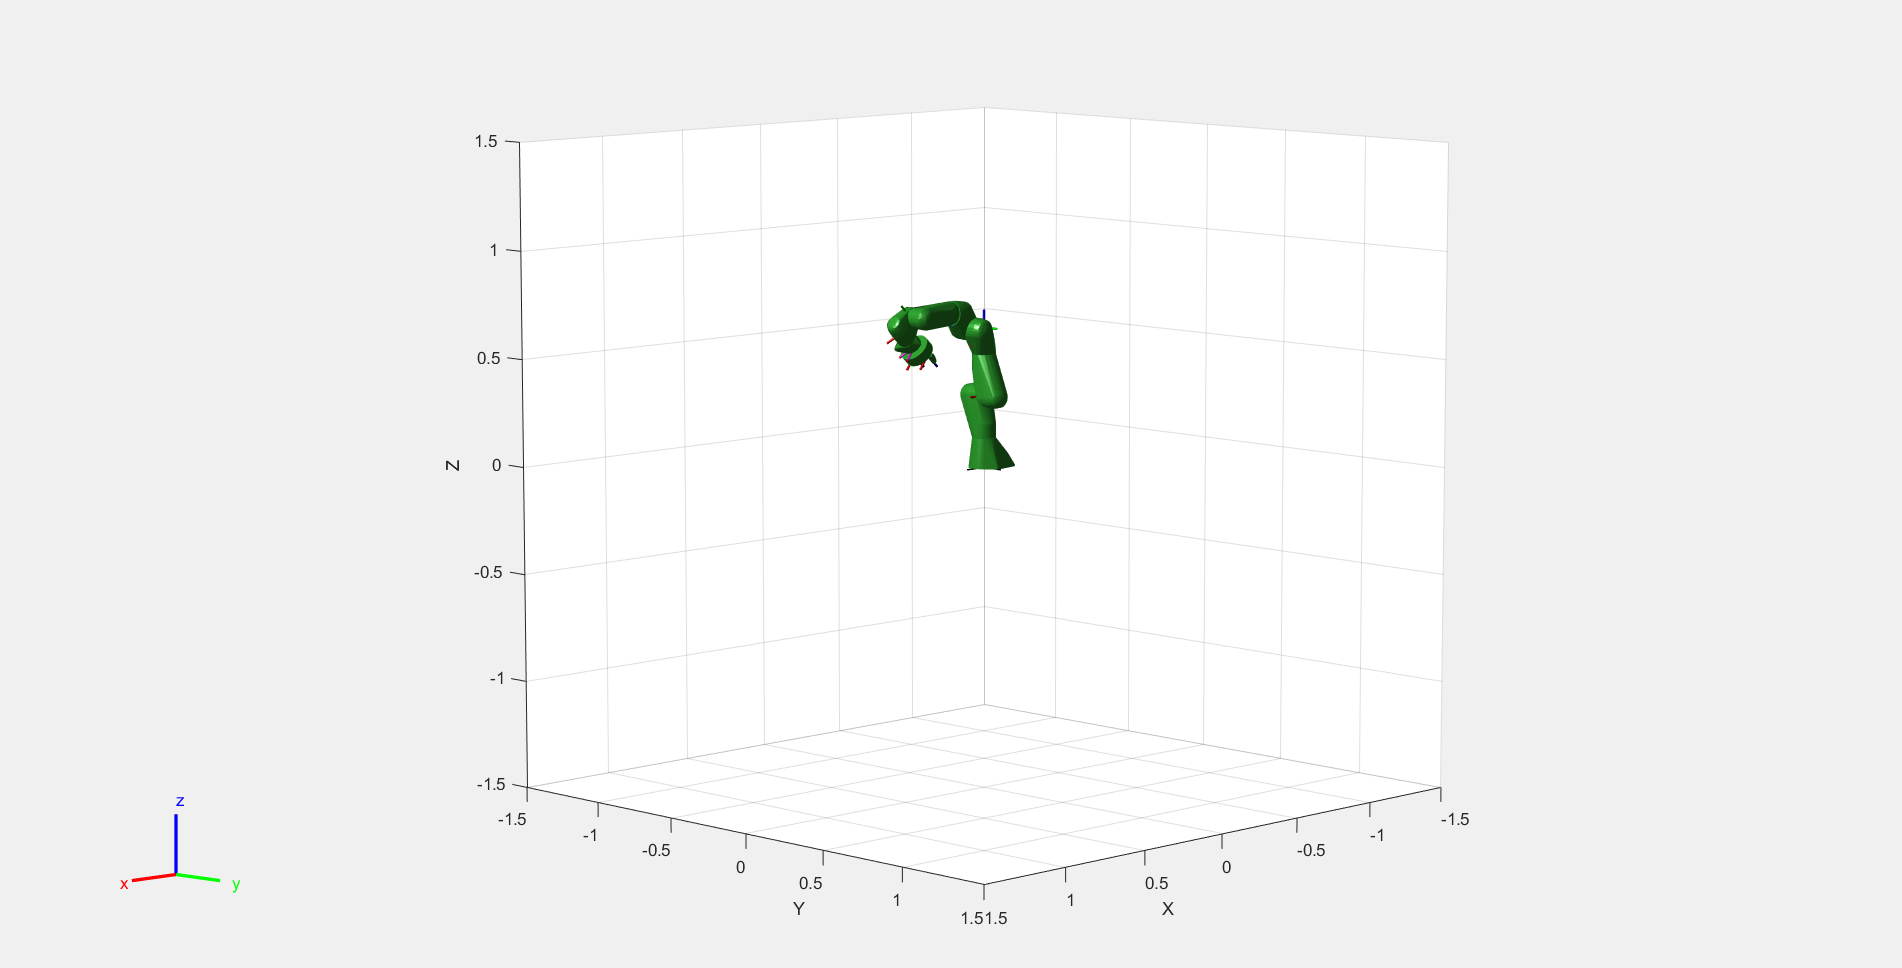

figure("Name","Pick and Place Using RRT",...
    "Units","normalized",...
    "OuterPosition",[0, 0, 1, 1],...
    "Visible","on");
show(franka,config,"Visuals","off","Collisions","on");
hold on

for i = 1:length(env)
    show(env{i});
end

Check for missing argument or incorrect argument data type in call to function 'show'.

## Planner

Create the RRT path planner and specify the robot model and the environment. Define some parameters, which are later tuned, and specify the start and goal configuration for the robot.

planner = manipulatorRRT(franka, env);

planner.MaxConnectionDistance = 0.3;
planner.ValidationDistance = 0.1;

startConfig = config;
goalConfig = [0.2371   -0.0200    0.0542   -2.2272    0.0013    2.2072   -0.9670    0.0400    0.0400];


Plan the path between configurations. The RRT planner should generate a rapidly-exploring tree of random configurations to explore the space and eventually returns a collision-free path through the environment. Before planning, reset the MATLAB's random number generator for repeatabile results.

rng('default');
path = plan(planner,startConfig,goalConfig);

To visualize the entire path, interpolate the path into small steps. By default, the `interpolate` function generates all of the configurations that were checked for feasibility (collision checking) based on the `ValidationDistance` property. 

interpStates = interpolate(planner, path);

for i = 1:2:size(interpStates,1)
    show(franka, interpStates(i,:),...
        "PreservePlot", false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 1: MaxConnectionDistance = 0.3")
    drawnow;
end

## Tuning the Planner

Tune the path planner by modifying the `MaxConnectionDistance`, `ValidationDistance`, `EnableConnectHeuristic` properties on the `planner` object.

Setting the `MaxConnectionDistance` property to a larger value causes longer motions in the planned path, but also enables the planner to greedily explore the space. Use `tic` and` toc` functions to time the `plan` function for reference on how these parameters can affect the execution time.

planner.MaxConnectionDistance = 5;
tic
path = plan(planner,startConfig,goalConfig);
toc

Notice the change in the path. The robot arm swings much higher due to the larger connection distance.

interpStates = interpolate(planner, path);

for i = 1:2:size(interpStates, 1)
    show(franka,interpStates(i,:),...
        "PreservePlot",false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 2: MaxConnectionDistance = 5")
    drawnow;
end

Setting the `ValidationDistance` to a smaller value enables finer validation of the motion along an edge in the planned path. Increasing the number of configurations to be validated along a path leads to longer planning times. A smaller value is useful in case of a cluttered environment with a lot of collision objects. Because of the small validation distance, `interpStates` has a larger number of elements. For faster visualization, the `for` loop skips more states in this step for faster visualization.

planner.MaxConnectionDistance = 0.3;
planner.ValidationDistance = 0.01;

tic
path = plan(planner,startConfig,goalConfig);
toc
interpStates = interpolate(planner,path);
for i = 1:10:size(interpStates,1)
    show(franka, interpStates(i,:),...
        "PreservePlot",false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 3: ValidationDistance = 0.01")
    drawnow;
end

The connect heuristic allows the planner to greedily join the start and goal trees. In places where the environment is less cluttered, this heuristic is useful for shorter planning times. However, a greedy behavior in a cluttered environment leads to wasted connection attempts. Setting the `EnableConnectHeuristic` to `false` gives shorter planning times and higher success rate of finding a valid plan, but may lead to longer paths. The `ValidationDistance` is set back to 0.1 to improve planning time lost from disabling the greedy connect.

planner.ValidationDistance = 0.1;
planner.EnableConnectHeuristic = false;

tic
path = plan(planner,startConfig,goalConfig);
toc
interpStates = interpolate(planner,path);
for i = 1:2:size(interpStates,1)
    show(franka, interpStates(i,:), ...
        "PreservePlot",false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 4: EnableConnectHeuristic = false")
    drawnow;
end

## Attach the Can to the End-Effector

After tuning the planner for the desired behavior, follow the pick-and-place workflow where the robot moves an object through the environment. This example attaches a cylinder, or can, to the end-effector of the robot and moves it to a new location. For each configuration, the planner checks for collisions with the cylinder mesh as well.

% Create can as a rigid body
cylinder1 = env{3};
canBody = rigidBody("myCan");
canJoint = rigidBodyJoint("canJoint");

% Get current pose of the robot hand.
startConfig = path(end, :);
endEffectorPose = getTransform(franka,startConfig,"panda_hand");

% Place can into the end effector gripper.
setFixedTransform(canJoint,endEffectorPose\cylinder1.Pose); 

% Add collision geometry to rigid body.
addCollision(canBody,cylinder1,inv(cylinder1.Pose));
canBody.Joint = canJoint;

% Add rigid body to robot model.
addBody(franka,canBody,"panda_hand");

% Remove object from environment.
env(3) = [];

After the can has been attached to the robot arm, specify a goal configuration for placing the object. Modify the planner parameters. Plan a path from start to goal. Visualize the path. Notice the can clears the wall.

goalConfig = [-0.6564 0.2885 -0.3187 -1.5941 0.1103 1.8678 -0.2344 0.04 0.04];

planner.MaxConnectionDistance = 1;
planner.ValidationDistance = 0.2;
planner.EnableConnectHeuristic = false;
path = plan(planner,startConfig,goalConfig);

interpStates = interpolate(planner,path);

hold off
show(franka,config,"Visuals","off","Collisions","on");
hold on
for i = 1:length(env)
    show(env{i});
end

for i = 1:size(interpStates,1)
    show(franka,interpStates(i,:),...
        "PreservePlot", false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 5: Place the Can")
    drawnow;
    if i == (size(interpStates,1))
        view([80,7])
    end
end


### Shorten the Planned Path

To shorten your path, use the `shorten` function and specify a number of iterations. A small value for the `ValidationDistance` property combined with a large number of iterations can result in large computation times.

shortenedPath = shorten(planner,path,20);


interpStates = interpolate(planner,shortenedPath);
for i = 1:size(interpStates,1)
    show(franka, ...
        interpStates(i, :),  ...
        "PreservePlot", false, ...
        "Visuals", "off", ...
        "Collisions", "on");
    drawnow;
    title("Plane 6: Shorten the Path")
    if i > (size(interpStates,1)-2)
        view([80,7])
    end
end
hold off

*Copyright 2020 The MathWorks, Inc.*